# Aula 14 - Controle Ótimo

**Seja o sistema já definido pelo exercício:**

clear
close all
A=[0,1,0;980,0,-2.8;0, 0,-100];
B=[0;0;100];
C=[1,0,0];
sys_ma=ss(A,B,C,0);

A matriz A é 3x3, então o sistema é de terceira ordem ( $n=3$ ) e precisa de 3 variáveis de estado. 

Além disso, por B vemos que o sistema tem uma única entrada e por C vemos que o sistema tem uma única saída, o que indica que é um sistema SISO.

**Verificação da Controlabilidade e Observabilidade:**

ct=rank(ctrb(A,B))

ct = 3

ob=rank(obsv(A,C))

ob = 3

O sistema é controlável e observável.

**Controle Ótimo:**

Tem como objetivo minimizar o funcional $J_{\infty}(t)=\int_t^\infty[X^T(\tau)Q(\tau)X(\tau)+u^T(\tau)R(\tau)u(\tau)]d\tau$ , no qual a primeira parcela representa a precisão que queremos e a segunda parcela representa a energia gasta pelo controlador. Fazemos isso calculando a matriz de controle $K$ usando como parâmetro as matrizes $Q_{nxn}$ e $R_{mxm}$, sendo $n$ o número de variáveis de estado e $m$ o número de entradas. A matriz $Q$ representa em sua diagonal a importância da precisão do controle para cada variável de estado e a matriz $R$ o quanto de energia desejamos gastar. Como dejamos controlar apenas a primeira variável de estado, usaremos o peso 1 para ela e 0.01 para as outras duas e faremos $R=P^2$. Assim, quando P diminui, damos mais importância para a posição e quando P aumenta damos mais importância pra o gasto de energia no controlador.

**Calculo de K:**

P=0.1;
R=P^2;
Q=[1,0,0;0,0.01,0;0,0,0.01];
[K,S,e] = lqr(sys_ma,Q,R);
K

K = 	1.0e+03 *

   -1.2093   -0.0386    0.0010


**Sistema em malha fechada:**

Kr=1;
Amf=A-B*K;
Bmf=B*Kr;
sys_mf=ss(Amf,Bmf,C,0);
Kr=1/dcgain(sys_mf);
Bmf=B*Kr;
sys_mf=ss(Amf,Bmf,C,0);

**Simulando entrada degrau de 0.01:**

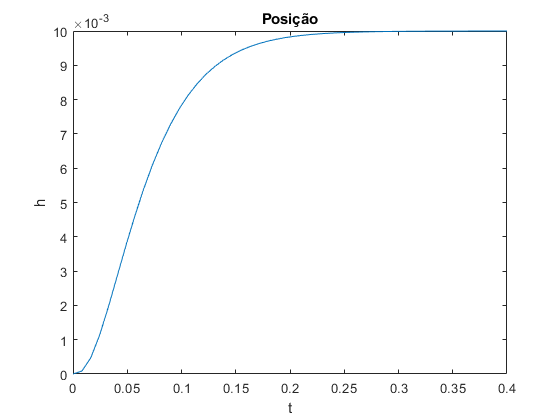

t=linspace(0,0.4,50); % tempo da simulação
r=0.01*ones(1,length(t)); % entrada degrau de 0.01
[y,t,x] = lsim(sys_mf,r,t);
plot(t,y)
title('Posição')
ylabel('h')
xlabel('t')

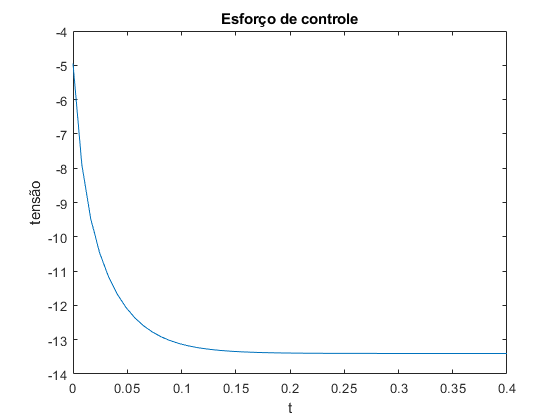

u=K*x'+(r*Kr);
plot(t,u)
title('Esforço de controle')
ylabel('tensão')
xlabel('t')